# Step 1: Read Image

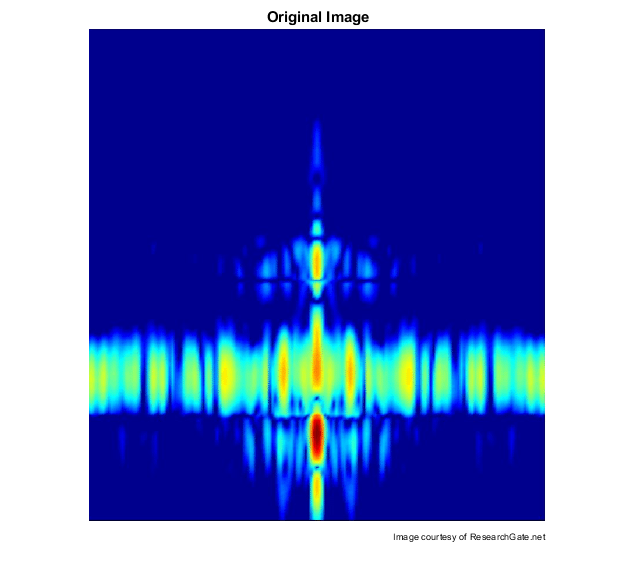

I = imread('test.png');
imshow(I)
title('Original Image');
text(size(I,2),size(I,1)+15, ...
    'Image courtesy of ResearchGate.net', ...
    'FontSize',7,'HorizontalAlignment','right');

## Step 2: Convert to Grayscale Image

Convert image to grayscale and display to screen.

Note: This step is important for the Sobel filter to work correctly.

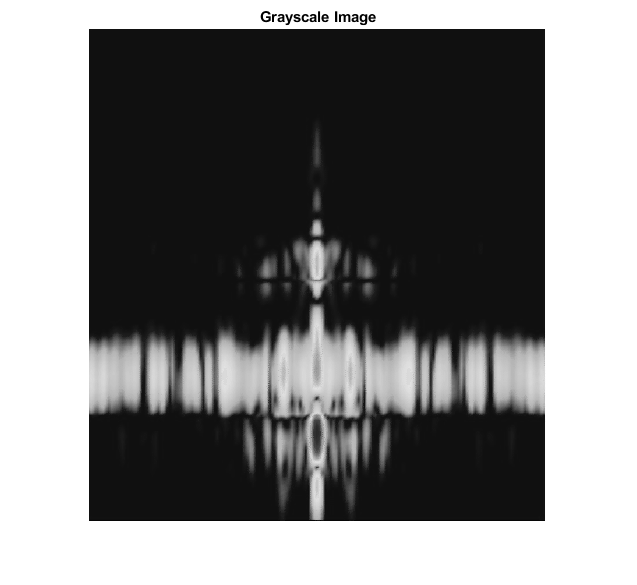

grayScale = rgb2gray(I);
% Display the resulting binary gradient mask
imshow(grayScale)
title('Grayscale Image')

## Step 3: Detect Edges with Sorbel filter

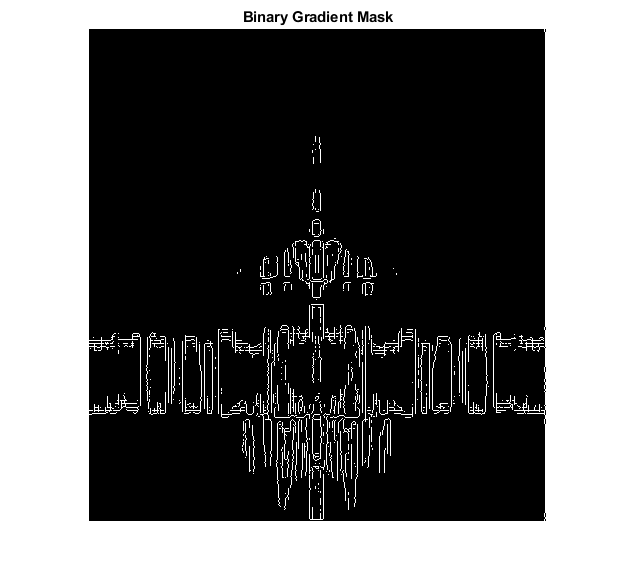

[~,threshold] = edge(grayScale,'sobel');
fudgeFactor = 0.5;
BWs = edge(grayScale,'sobel',threshold * fudgeFactor);

% Display the resulting binary gradient mask
imshow(BWs)
title('Binary Gradient Mask')

## Step 4: Dilate the Image

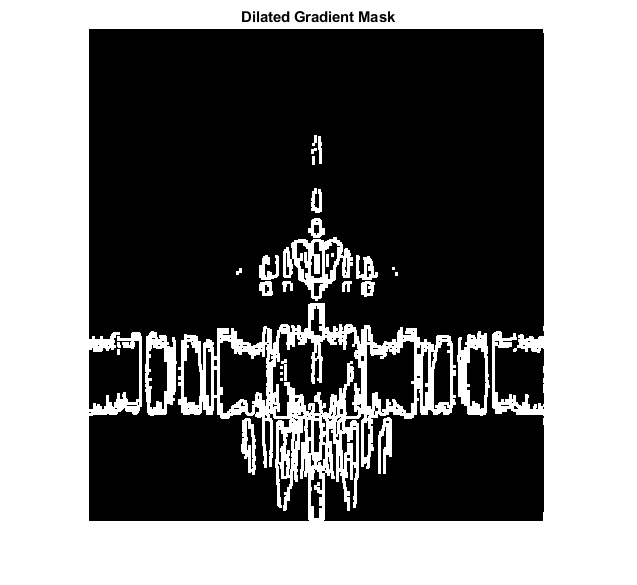

se90 = strel('line',3,90);
se0 = strel('line',3,0);

% Dilate the binary gradient mask
BWsdil = imdilate(BWs,[se90 se0]);
imshow(BWsdil)
title('Dilated Gradient Mask')

## Step 5: Fill the Interior Gaps

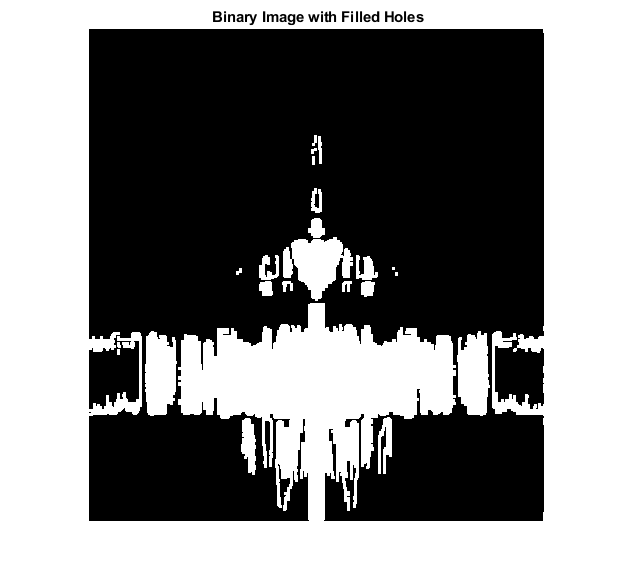

BWdfill = imfill(BWsdil,'holes');
imshow(BWdfill)
title('Binary Image with Filled Holes')

## Step 6: Remove Connected Objects on Border

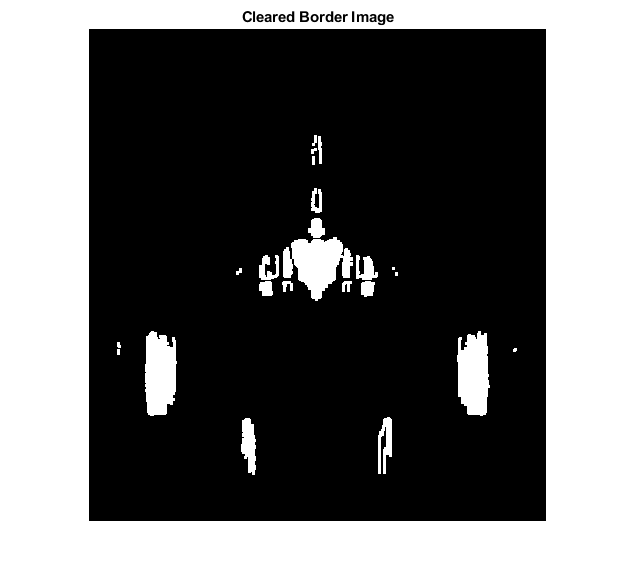

BWfinal = imclearborder(BWdfill,4);
imshow(BWfinal)
title('Cleared Border Image')

## Visualize the Segmentation

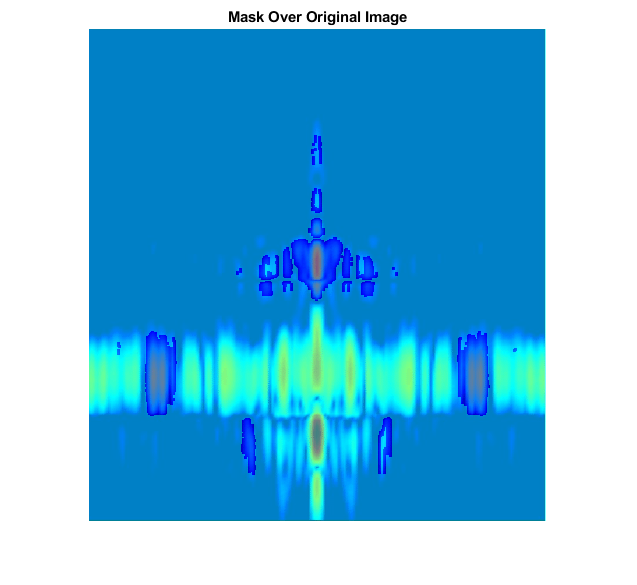

% Create categorical labels based on the image contents
stringArray = repmat("table", size(BWfinal));
stringArray(BWfinal) = "object";
categoricalSegmentation = categorical(stringArray);

% Fuse the categorical labels with the original image
mask = labeloverlay(I,categoricalSegmentation);
imshow(mask);
title('Mask Over Original Image')

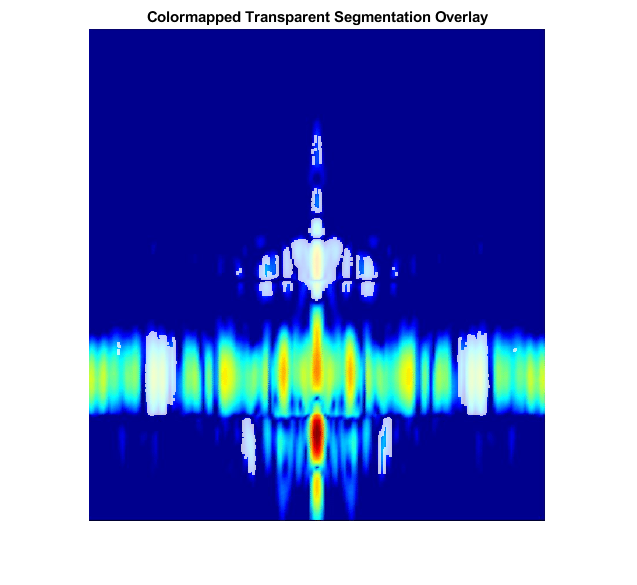


% Fuse the original image with only one label from the categorical
% segmentation
C = labeloverlay(I,categoricalSegmentation,'IncludedLabels',"object",'Colormap','white','Transparency',0.25);
imshow(C)
title('Colormapped Transparent Segmentation Overlay')